##     Contents of this script

This script generates dummy data to experiment with magnet search and collection:

- random placement of magnets on the board;

- array of sensor measures on the board.

You can use this data to test:

- magnet detection strategies;

- magnet collection strategies;

- theoretical model of sensor renspose to magnets.

## Initialisation of main parameters

We first set some parameters defining the size (in cm) of the board where magnets will be placed and the resolution with which we will scan this field (in measures per cm). The resolution will allow to define a array of measures that are a digital and discrete representation of the real magnetic field on the board.

boardSizeX = 50; % in cm
boardSizeY = 30; % in cm
gridResolution = 1; % in number of measures per cm 

We then define number of magnets that will be put on this board and their diameter in cm (assuming they are all the same size and have a regular round shape).

numberMagnets = 11; % dimentionless
magnetDiameter = 2; % in cm

## Sensor response

Then we need to define the way the sensors will react to passing over magnets. As a first working estimation, we consider that the sensors' response to the magnetic fields created by the magnets has a $e^{-{\frac{d}{\delta }}^s }$shape where *d* is the distance to the center of the magnet, $\delta$ is the diameter of the magnet, and *s* denotes the slope with wich the response of the sensor decreases with distance to the center of the magnet. But you may discover with experimentation that the sensor response may be different from this and may want to change this.

Also, the actual measurements may not exactly fit the values you would theoretically expect to measure. There may be some **background noise or random error **involved. To take account of that, we add to the sensor's response a term $\alpha e^{-r^{\beta } }$ where *r* is a random number between 0 and 1, and $\alpha$is the maximal range of the error, and $\beta$ denotes the frequency of large random errors (the higher $\beta$ is, the less frequent are large errors). Here again, you may find that the statistical distribution of random errors is different from this and may want to change that term.

Here is a plot of the sensor response over distance so you can have a look at it and play with the parameters. Notice that the sensor response is computed by the fuction *sensorResponse *which is at the end of the script. To tweak the sensor response, you would need to change teh code in this function.

### Code

x = -2*magnetDiameter:0.05:2*magnetDiameter;
y = [];
for i = x
    y = [y, sensorResponse(i, magnetDiameter)];
end

### Plot

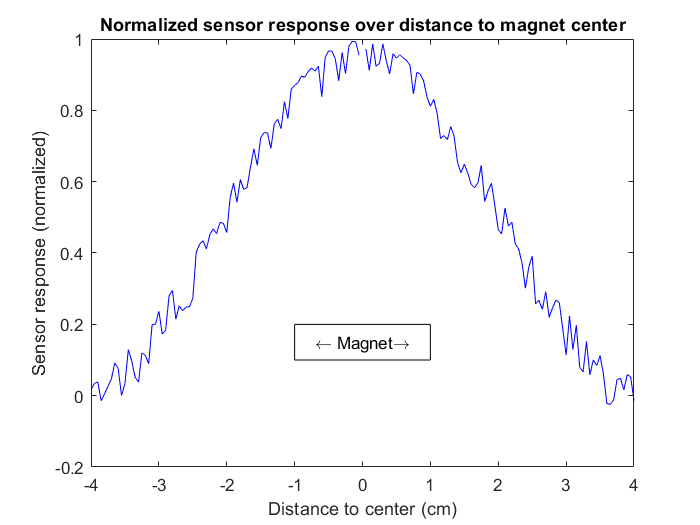

plot(x,y,'b')
title('Normalized sensor response over distance to magnet center')
xlabel('Distance to center (cm)')
ylabel('Sensor response (normalized)')
hold on;
rectangle('Position',[-magnetDiameter/2, 0.1, magnetDiameter, 0.1])
text(0, 0.15, '\leftarrow Magnet\rightarrow', 'HorizontalAlignment', 'center')
hold off;

## Magnet positions

Let's now generate random magnet positions on the 2D board. Note that we are defining 2D coordinates for magnets in floating numbers (real numbers) and not in integers. This is because we consider that the magnets can be placed *anywhere *on the board, and not only on the discrete digitalized grid. 

Each time we generate a random position, we check that it does not overlap with an already placed magnet. Two magnets overlap when the distance between their centers is lower than their radius. 

### Code

% initialisation of an array to host the 2D coordinates of the center point each magnet
magnetCenters = []; 
% the following is repeated as long as we have created as many magnets as we need
while size(magnetCenters,2) < numberMagnets 
    % we generate random 2D coordinates for the center of a possible new magnet. Note that we don't use 
    % the whole board but shrink it from the magnet radius. Why: because we don't want magnets to
    % stick outside of the board.
    magnetCoord = [...
        rand * (boardSizeX - magnetDiameter) + magnetDiameter/2; ...
        rand * (boardSizeY - magnetDiameter) + magnetDiameter/2 ...
        ]; 
    % here we check that there is no overlap with an existing magnet, if any.
    % if there is an overlap, we dismiss the new magnet
    % if not, we add the magnet to the array.
    if size(magnetCenters,2)==0 || min(vecnorm(magnetCenters-magnetCoord)) > magnetDiameter + 5
        magnetCenters = [magnetCenters magnetCoord];
    end
end

### Plot

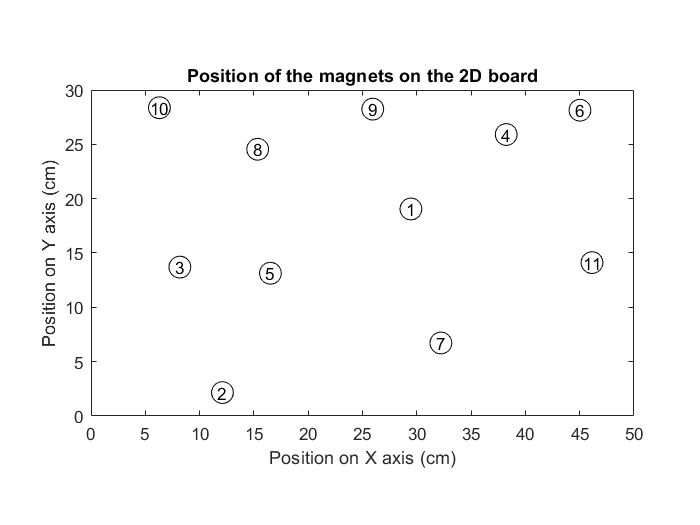

plot(magnetCenters(1,:),magnetCenters(2,:),'w*')
title('Position of the magnets on the 2D board')
xlabel('Position on X axis (cm)')
ylabel('Position on Y axis (cm)')
xlim([0 boardSizeX])
ylim([0 boardSizeY])
pbaspect([boardSizeX boardSizeY 1])
for i = 1:numberMagnets
    text(magnetCenters(1,i),magnetCenters(2,i), num2str(i), 'HorizontalAlignment', 'center')
end
hold on;
for i = 1:numberMagnets
    rectangle('Position',[ ...
        magnetCenters(1,i)-magnetDiameter/2, ...
        magnetCenters(2,i)-magnetDiameter/2, ...
        magnetDiameter, ...
        magnetDiameter ...
        ],'Curvature',[1 1])
end
hold off;

## Shortest magnet collection path

The following code snippet identifies the shortest path to collect all magnets, assuming we start from the origin and we come back to the origin.

### Code

collectionPath = shortestPath(magnetCenters, "Nearest Neighbour");

### Plot

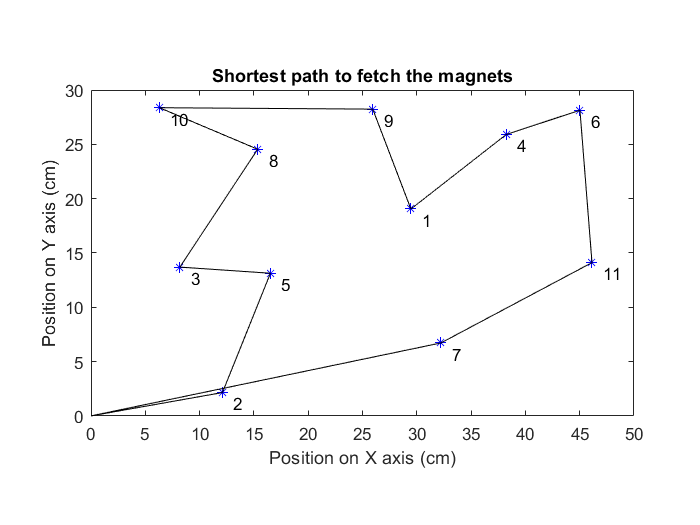

plot(magnetCenters(1,:),magnetCenters(2,:),'b*')
title('Shortest path to fetch the magnets')
xlabel('Position on X axis (cm)')
ylabel('Position on Y axis (cm)')
xlim([0 boardSizeX])
ylim([0 boardSizeY])
for i = 1:numberMagnets
    text(magnetCenters(1,i)+1,magnetCenters(2,i)-1, num2str(i))
end
pbaspect([boardSizeX boardSizeY 1])
hold on;
plot([0,magnetCenters(1, collectionPath(1))],[0,magnetCenters(2, collectionPath(1))],'k')
plot([0,magnetCenters(1, collectionPath(numberMagnets))],[0,magnetCenters(2, collectionPath(numberMagnets))],'k')
for i = 2:numberMagnets
    plot( ...
        [magnetCenters(1, collectionPath(i-1)), magnetCenters(1, collectionPath(i))], ...
        [magnetCenters(2, collectionPath(i-1)), magnetCenters(2, collectionPath(i))], ...
        'k');
end

## **Simulate the full array of possible measures**

Once we have the magnets placed, we can simulate all the measures we could do if the gantry would scan the whole board. The measures are stored in a *nm *matrix where *n *and *m *are the width and depth of the board multiplied by the sensing resolution. 

### Code

% initialisation of the matrix that will host all measures
sensedData = zeros( ...
    gridResolution * boardSizeX, ...
    gridResolution * boardSizeY ...
    );

% for each line, for each column, we create a measure
% this measure is the sum of the magnetic field created by each magnet
for i = 1:size(sensedData,1)
    for j = 1:size(sensedData,2)
        sensedData(i,j) = sensorResponse( ...
            vecnorm(magnetCenters-[i/gridResolution;j/gridResolution]), ...
            magnetDiameter);
    end
end

### Plot

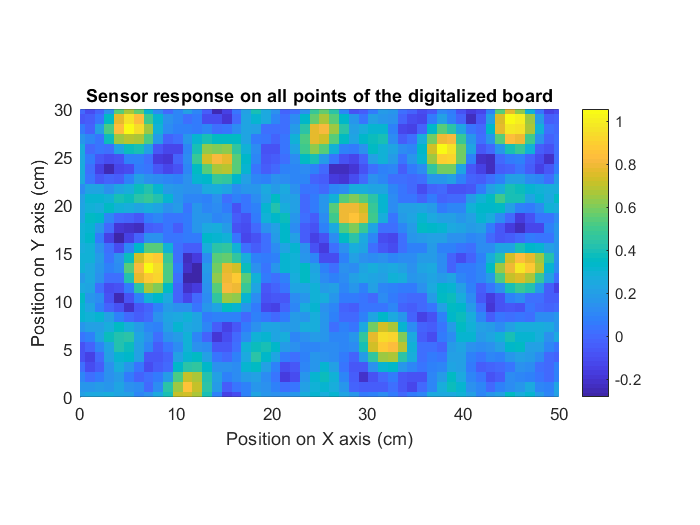

imagesc([0 boardSizeX],[0 boardSizeY], sensedData');
set(gca,'YDir','normal') % because otherwise imagesc plots the image flipped horizontally
colorbar
title('Sensor response on all points of the digitalized board')
xlabel('Position on X axis (cm)')
ylabel('Position on Y axis (cm)')
pbaspect([boardSizeX boardSizeY 1])
hold off;

## Cleaning data

The data we measured with the sensor is noisy. This may lead to false positives (we think we have found a magnet but there is nothing more than an measurment error). We may need a step to clean the data, that is, to remove false positives. The way the following bit of code is removing false positive is to smooth the data, that is, making a 2D average to remove high frequency peaks. It uses for this a [built-in Matlab function](https://uk.mathworks.com/help/matlab/data_analysis/convolution-filter-to-smooth-data.html).

### Code

% define the convolutoin filter to smooth the data
K = 0.125*ones(5);

% applies the convolution and get smoothed data
smoothedData = conv2(sensedData',K,'same');

### Plot

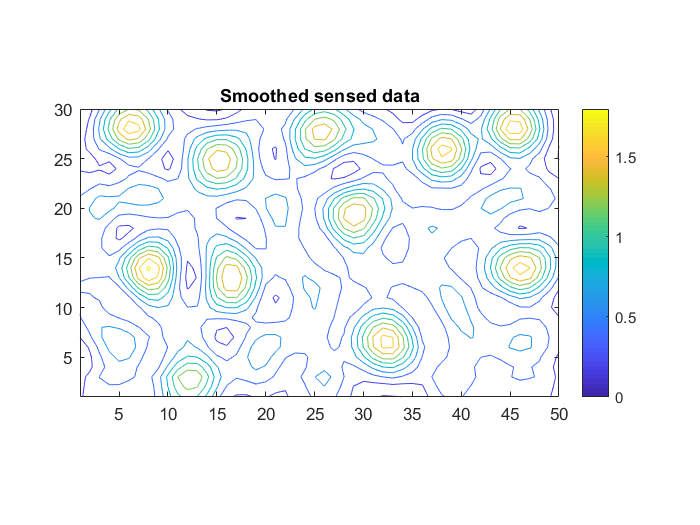

contour(smoothedData)
title('Smoothed sensed data')
colorbar
pbaspect([boardSizeX boardSizeY 1])

## Apply a **threshold**

Removes all data points that are below 0.7

### Code

for i = 1:size(smoothedData,1)
    for j = 1:size(smoothedData,2)
        if smoothedData(i,j) < 0.7
            smoothedData(i,j) = 0;
        end
    end
end

### Plot

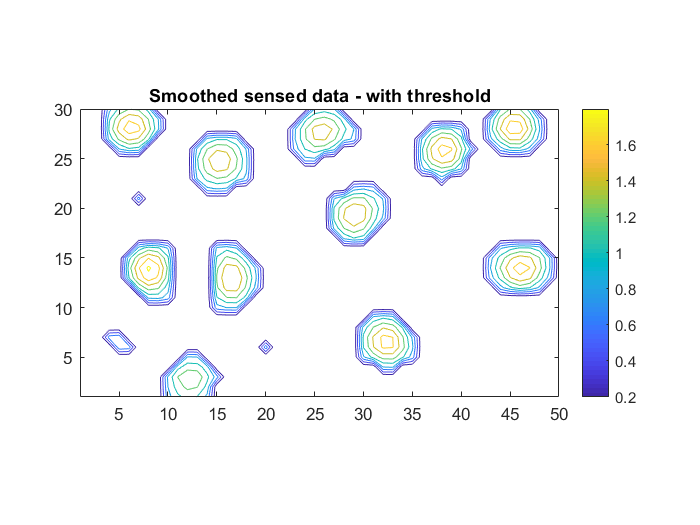

contour(smoothedData)
colorbar
title('Smoothed sensed data - with threshold')
pbaspect([boardSizeX boardSizeY 1])

function resp = sensorResponse(distances, diameter)
    noise = exp(-rand^2);
    measure = 0;
    for k = 1:size(distances,2)
        measure = measure + sin(distances(:,k))/distances(:,k);
    end
   resp = 0.8*measure + 0.2*noise;
end